%DEMO_ART Demonstrates the use of, and results from, the ART methods
%
% This script illustrates the use of the ART methods Kaczmarz, symmetric
% Kaczmarz, and randomized Kaczmarz.
%
% The script creates a parallel-beam CT test problem and solves it with the
% ART methods.  The exact image and the results from the methods are shown.
%
% See also: demo_cart, demo_constraints, demo_custom_all, demo_matrixfree,
% demo_relaxpar, demo_sirt, demo_stoprules, demo_training.

% Code written by: Per Christian Hansen, Jakob Sauer Jorgensen, and 
% Maria Saxild-Hansen, 2010-2017.

% This file is part of the AIR Tools II package and is distributed under
% the 3-Clause BSD License. A separate license file should be provided as
% part of the package. 
% 
% Copyright 2017 Per Christian Hansen, Technical University of Denmark and
% Jakob Sauer Jorgensen, University of Manchester.

clear, clc
fprintf(1,'Starting demo_art:\n\n');

Starting demo_art:




% Set the parameters for the test problem.
N = 50;           % The image is N-times-N..
phi = 0:2:178;  % No. of used angles.
p = 75;           % No. of parallel rays.

fprintf(1,'Creating a parallel-beam tomography test problem\n');

Creating a parallel-beam tomography test problem


fprintf(1,'with N = %2.0f, theta = %1.0f:%1.0f:%3.0f, and p = %2.0f.',...
    [N,phi(1),phi(2)-phi(1),phi(end),p]);

with N = 50, theta = 0:2:178, and p = 75.

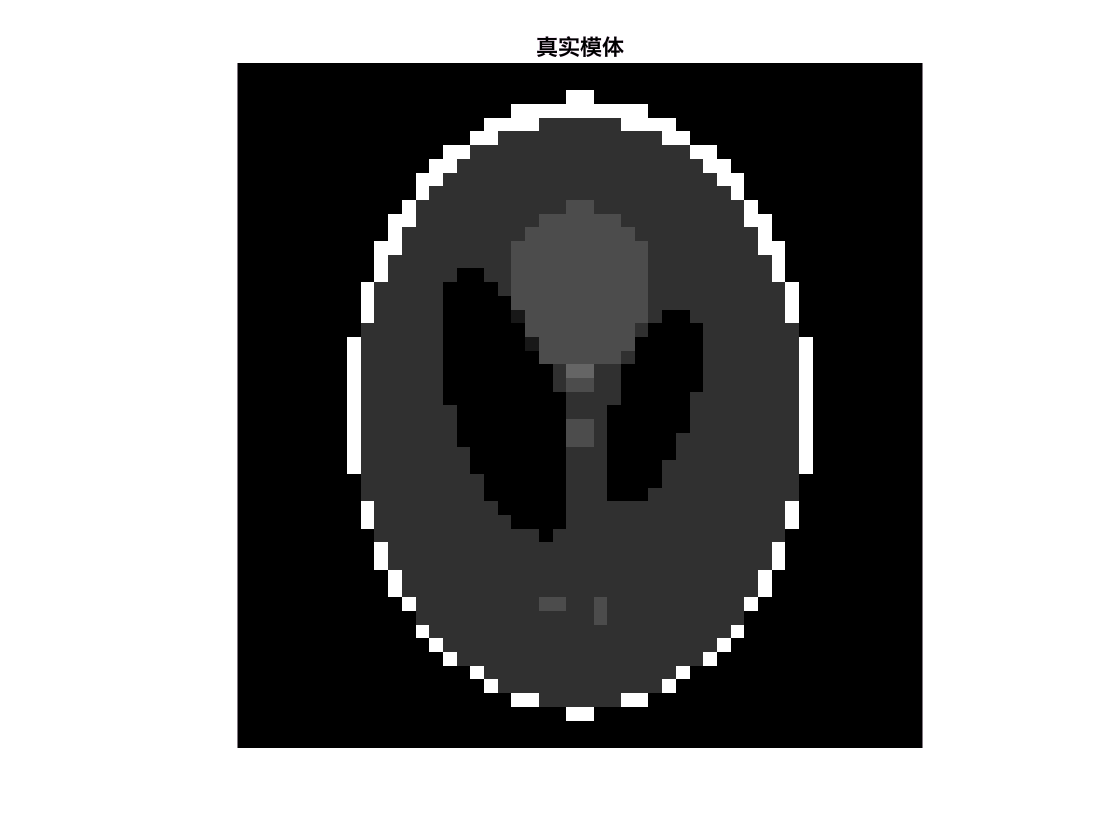


% Create the test problem.
[A,b,x] = paralleltomo(N,phi,p);

% Show the exact solution.
figure(1), clf
subplot()
% subplot(2,2,1)
imagesc(reshape(x,N,N)), colormap gray, axis image off
c = caxis;
title('真实模体')

fprintf(1, 'sparsity: %d', sum(x == 0))

sparsity: 1482

fprintf(1,'\n\n');


x0 = zeros(N ^ 2, 1);

## Necessary calculation for RSK

% tic
% cov_A = cov(A); % expensive
% eig_cov_A = eig(cov_A); % expensive too!
% min_eig = min(eig_cov_A(eig_cov_A > 0));
% ita = @(t, theta) (1 + t * min_eig) ^ (-theta);
% toc  % approx 4 min


## Iteration settings

geometric_seq = @(max) 2.^(0:floor(log2(max)));
k = geometric_seq(1024);
ita = @(t, theta, speed) (1 + speed * t) ^ (-theta);
% run_special = @(type, speed) art(type,A,b,k,x0,struct('waitbar',true, 'speed', speed));
% run_special_gaussian = @(type, speed) art(type,A,b,k,x0,struct('waitbar',true, 'noise','gaussian', 'speed', speed));
% run_special_cauchy = @(type, speed) art(type,A,b,k,x0,struct('waitbar',true, 'noise','cauchy', 'speed', speed));
run_general = @(type, theta, speed) art(type,A,b,k,x0,struct('waitbar',true,'ita', ita, 'theta', theta, 'speed', speed));
run_robust = @(type, theta, speed) art(type,A,b,k,x0,struct('waitbar',true,'ita', ita, 'theta', theta, 'robust', true, 'speed', speed));
run_general_gaussian = @(type, theta, speed) art(type,A,b,k,x0,struct('waitbar',true,'ita', ita, 'theta', theta, 'noise','gaussian', 'speed', speed));
run_robust_gaussian = @(type, theta, speed) art(type,A,b,k,x0,struct('waitbar',true,'ita', ita, 'theta', theta, 'robust', true, 'noise','gaussian', 'speed', speed));
run_general_cauchy = @(type, theta, speed) art(type,A,b,k,x0,struct('waitbar',true,'ita', ita, 'theta', theta, 'noise','cauchy', 'speed', speed));
run_robust_cauchy = @(type, theta, speed) art(type,A,b,k,x0,struct('waitbar',true,'ita', ita, 'theta', theta, 'robust', true, 'noise','cauchy', 'speed', speed));
plotter = Plotter(x, N, c, k, A);

## Perform the Kaczmarz iterations.

% type = 'kaczmarz';
% [Xrand, info] = run_special(type);
% plotter.plot(Xrand, type);

## Perform the randomized Kaczmarz iterations.

% type = 'randkaczmarz';
% [Xrand, info] = run_special(type);
% plotter.plot(Xrand, type);

## SK

% type = 'SK';
% [Xrand, info] = run_special(type);
% plotter.plot(Xrand, type);

## The special RSK in [26]

% [Xrand, info] = run_general('RSK', 0, 5e-6);
% plotter.plot(Xrand)

## Generalized RSK

% [Xrand, info] = run_general('RSK',1, 5e-6);
% plotter.plot(Xrand)

## Generalized RSK with theta = 0.5 

% [Xrand, info] = run_general('RSK',0.5, 5e-6);
% plotter.plot(Xrand)

## Robust RSK

% [Xrand, info] = run_robust('RSK',1 , 5e-6);
% plotter.plot(Xrand)

%% Generalized RSK under Gaussian Noise

% [Xrand, info] = run_general_gaussian('RSK',1, 5e-6);
% plotter.plot(Xrand)

%% Robust RSK under Gaussian Noise

% [Xrand, info] = run_robust_gaussian('RSK',1, 5e-6);
% plotter.plot(Xrand)

%% Generalized RSK under Cauchy Noise

% [Xrand, info] = run_general_cauchy('RSK',1, 5e-6);
% plotter.plot(Xrand)

%% Robust RSK under Cauchy Noise

% [Xrand, info] = run_robust_cauchy('RSK',1, 5e-6);
% plotter.plot(Xrand)

%% compare without Noise

[X_RSK0, info] = run_general('RSK',0, 5e-6);

ita decayed to 1.000000 by speed 0.000005 in the end


[X_RSK1, info] = run_general('RSK',1, 5e-6);

ita decayed to 0.016752 by speed 0.000005 in the end


[X_RRSK, info] = run_robust('RSK',1, 5e-6);

ita decayed to 0.016752 by speed 0.000005 in the end


相对误差下降至 0.000000 %


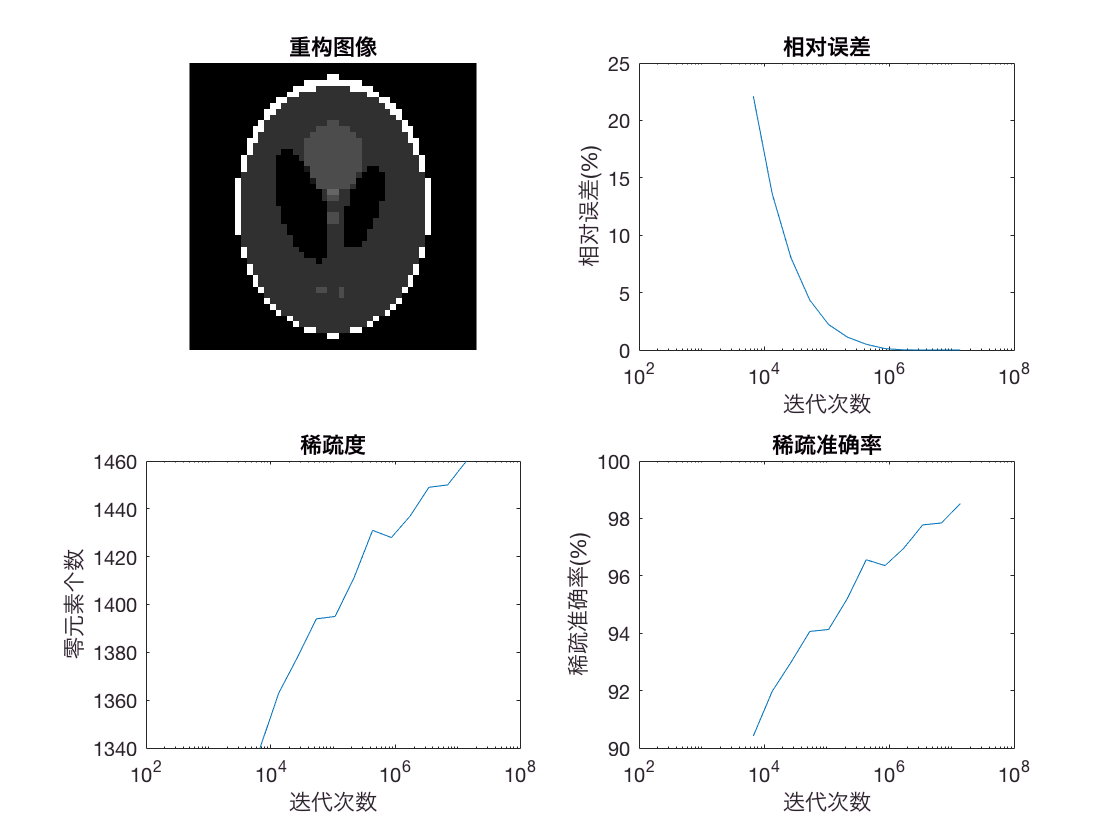

plotter.plot(X_RSK0)

相对误差下降至 0.092636 %


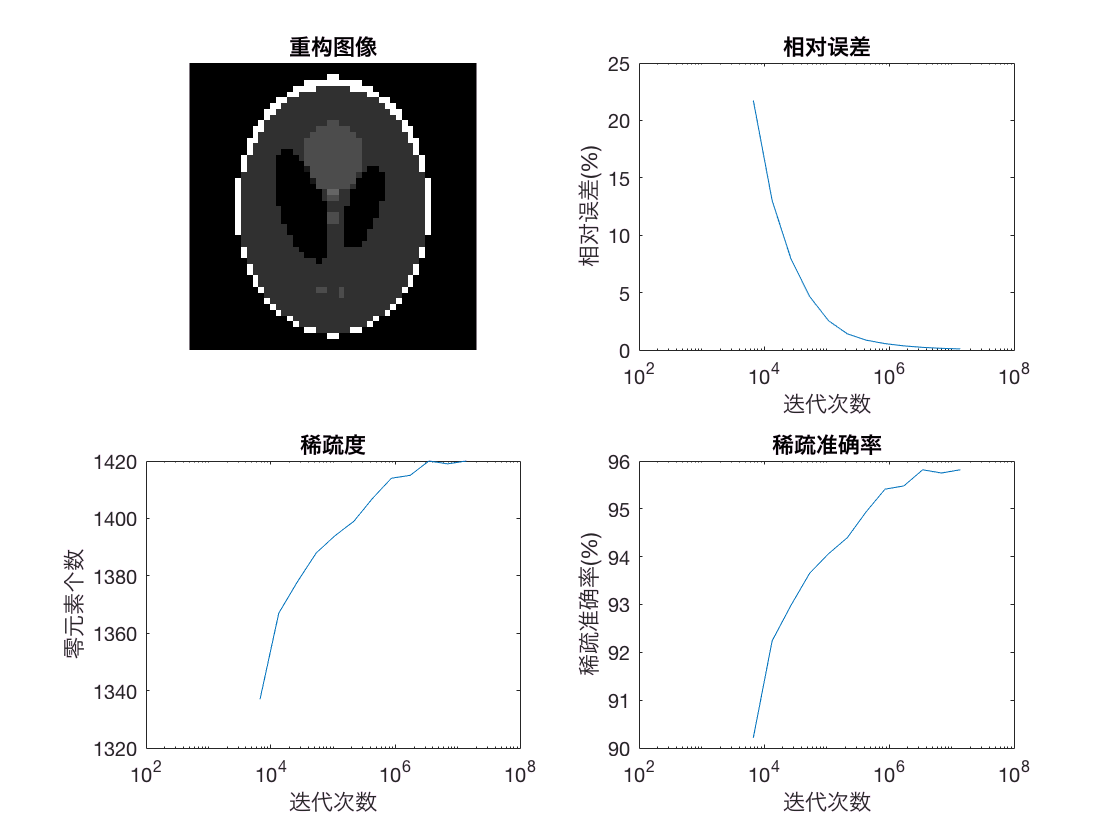

plotter.plot(X_RSK1)

相对误差下降至 0.479466 %


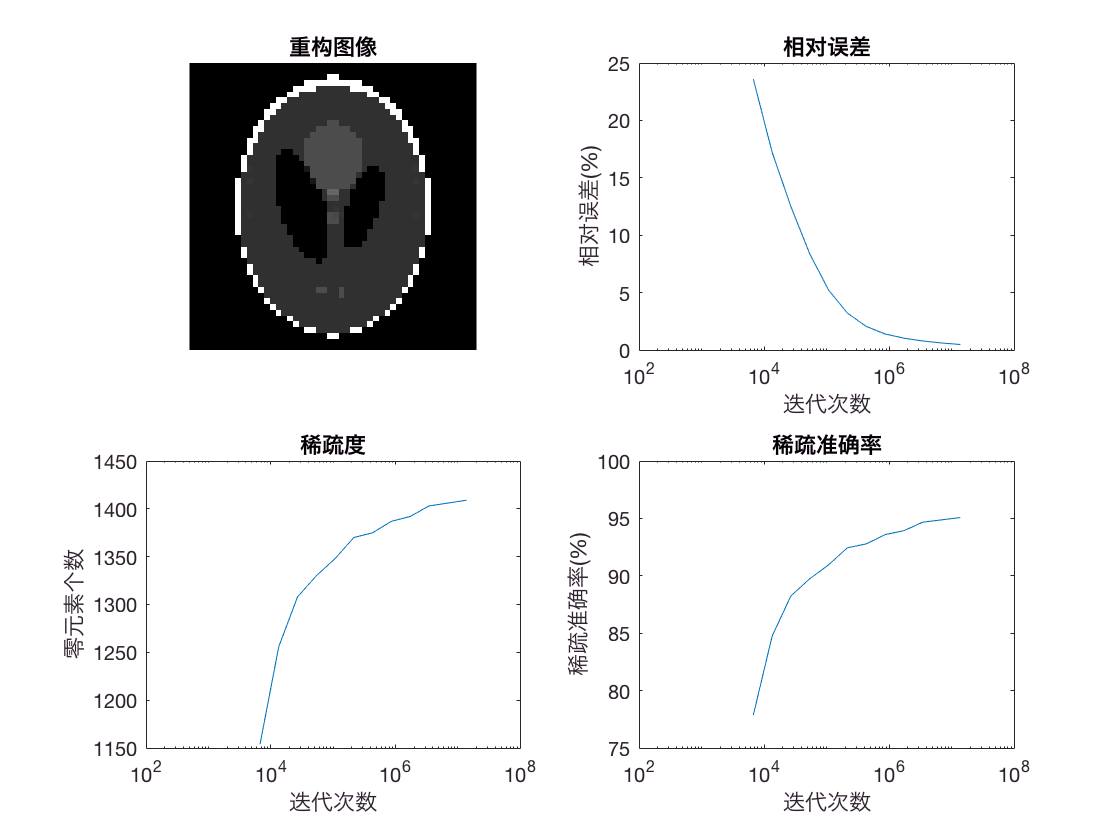

plotter.plot(X_RRSK)

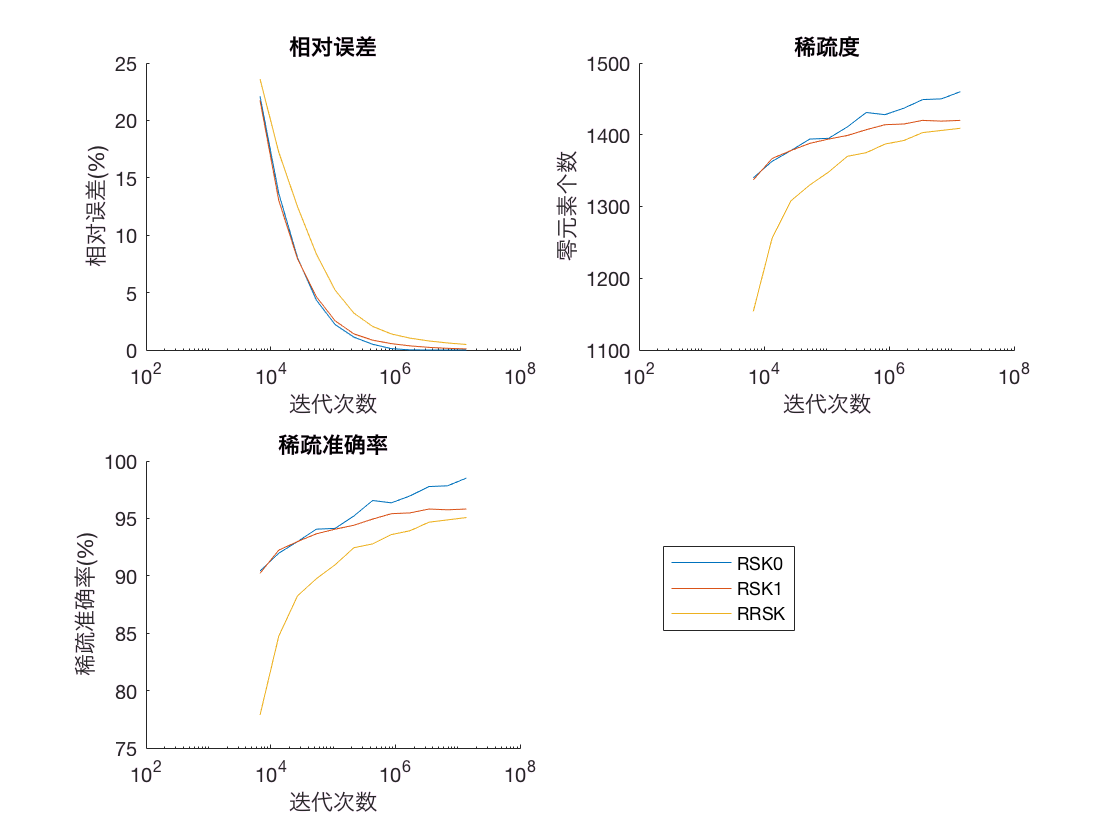

plotter.compare({'RSK0', 'RSK1', 'RRSK'}, X_RSK0, X_RSK1, X_RRSK)

%% compare under Gaussian Noise

[X_RSK0, info] = run_general_gaussian('RSK',0, 5e-6);

add gaussian noise


ita decayed to 1.000000 by speed 0.000005 in the end


[X_RSK1, info] = run_general_gaussian('RSK',1, 5e-6);

add gaussian noise
ita decayed to 0.016752 by speed 0.000005 in the end


[X_RRSK, info] = run_robust_gaussian('RSK',1, 5e-6);

add gaussian noise
ita decayed to 0.016752 by speed 0.000005 in the end


相对误差下降至 32.859061 %


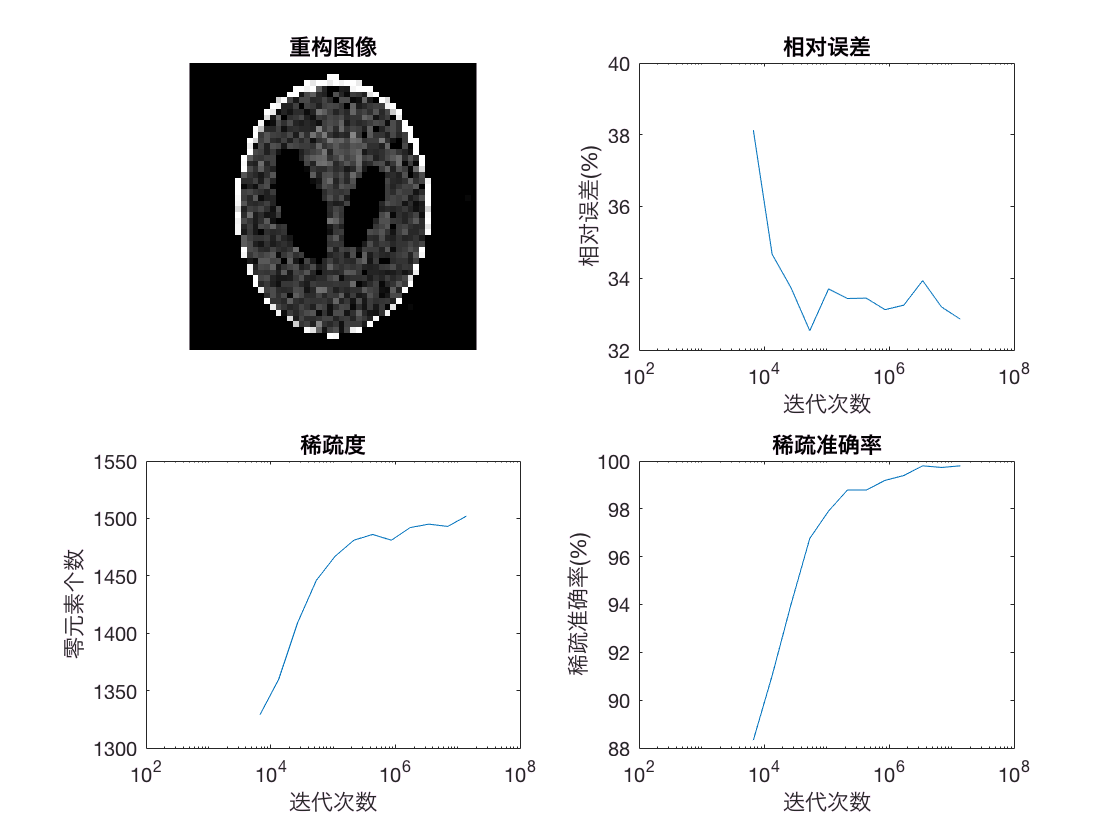

plotter.plot(X_RSK0)

相对误差下降至 3.673610 %


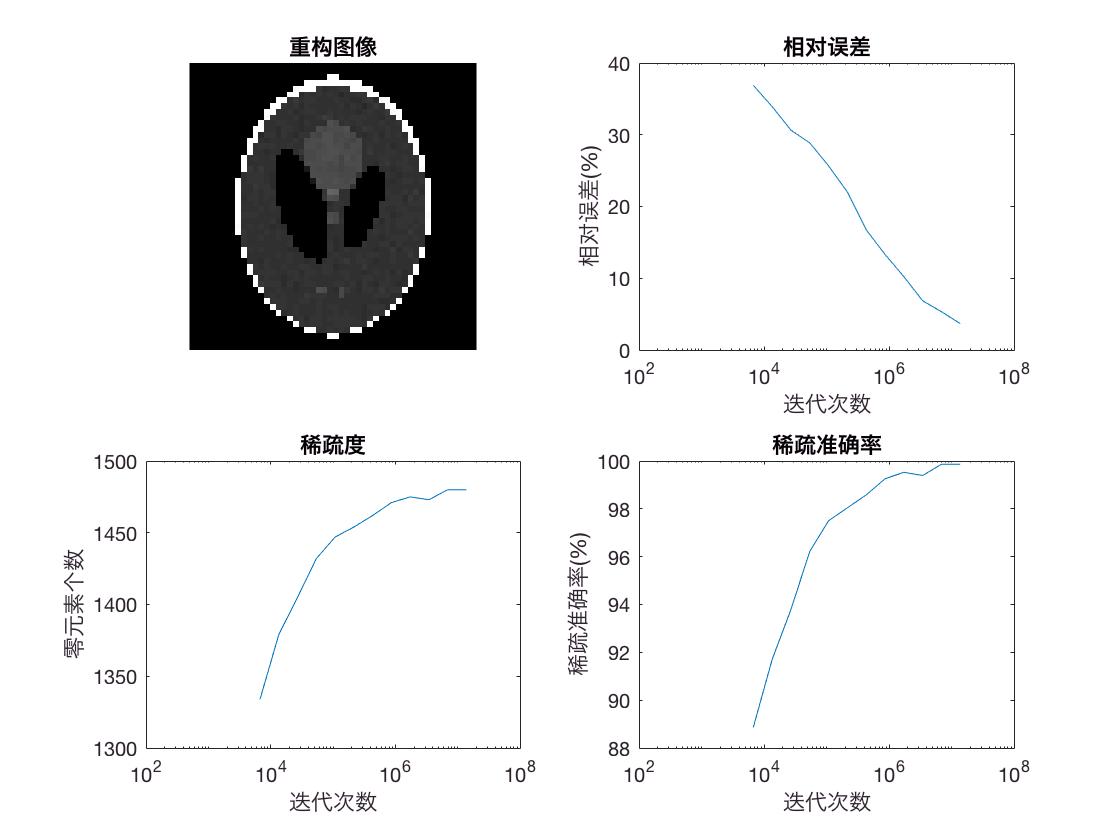

plotter.plot(X_RSK1)

相对误差下降至 2.529082 %


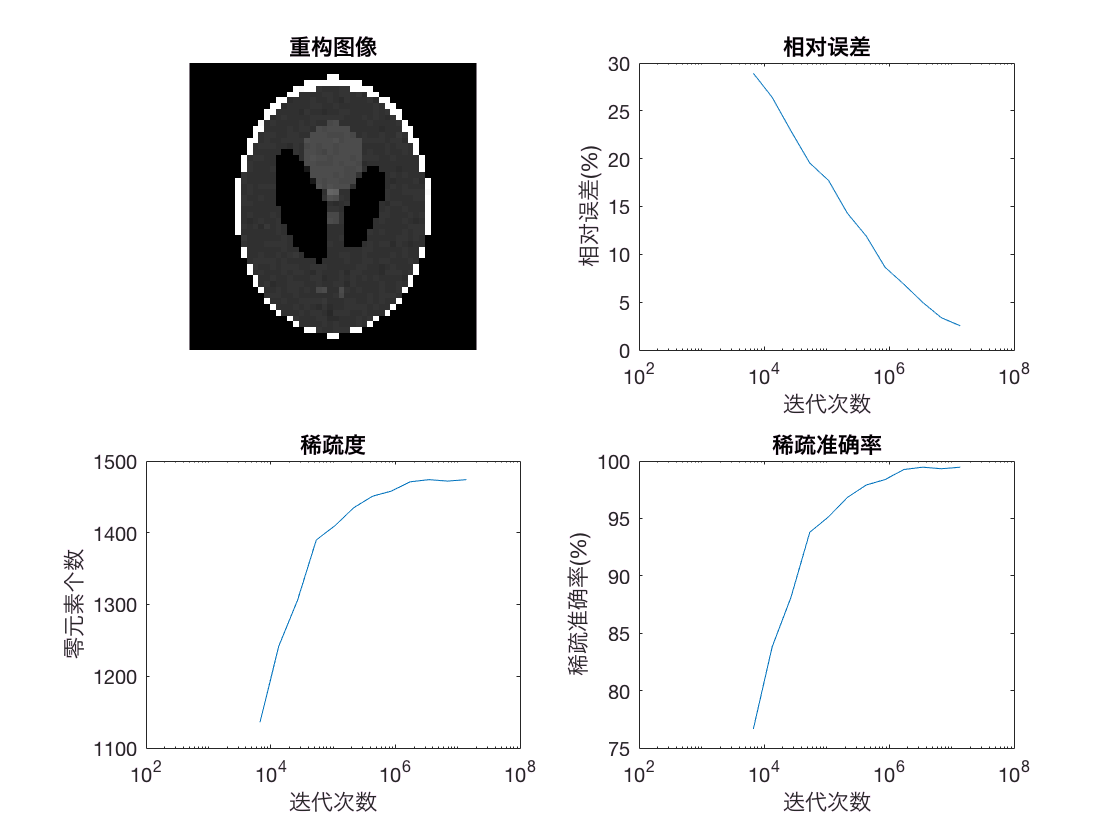

plotter.plot(X_RRSK)

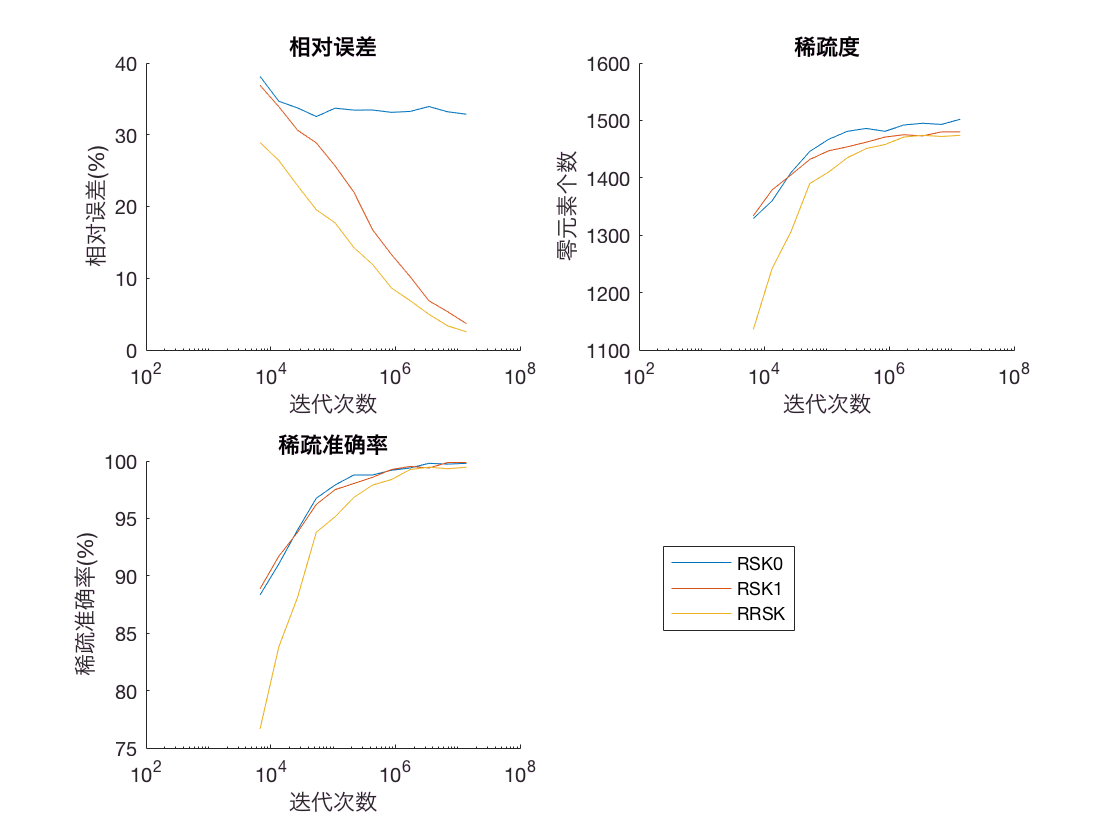

plotter.compare({'RSK0', 'RSK1', 'RRSK'}, X_RSK0, X_RSK1, X_RRSK)

%% compare under Cauchy Noise

[X_RSK0, info] = run_general_cauchy('RSK',0, 5e-6);

add cauchy noise
ita decayed to 1.000000 by speed 0.000005 in the end


[X_RSK1, info] = run_general_cauchy('RSK',1, 5e-6);

add cauchy noise
ita decayed to 0.032951 by speed 0.000005 in the end


[X_RRSK, info] = run_robust_cauchy('RSK',1, 5e-6);

add cauchy noise
ita decayed to 0.032951 by speed 0.000005 in the end


相对误差下降至 39.161995 %


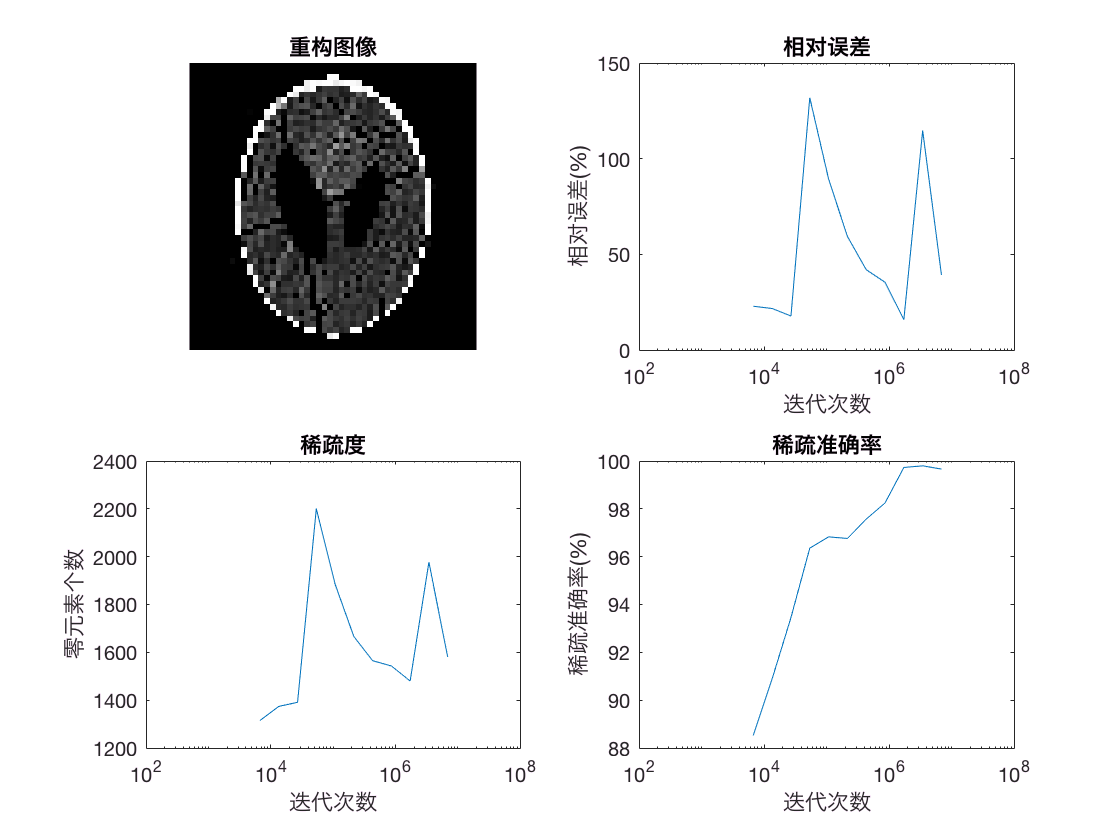

plotter.plot(X_RSK0)

相对误差下降至 83.673934 %


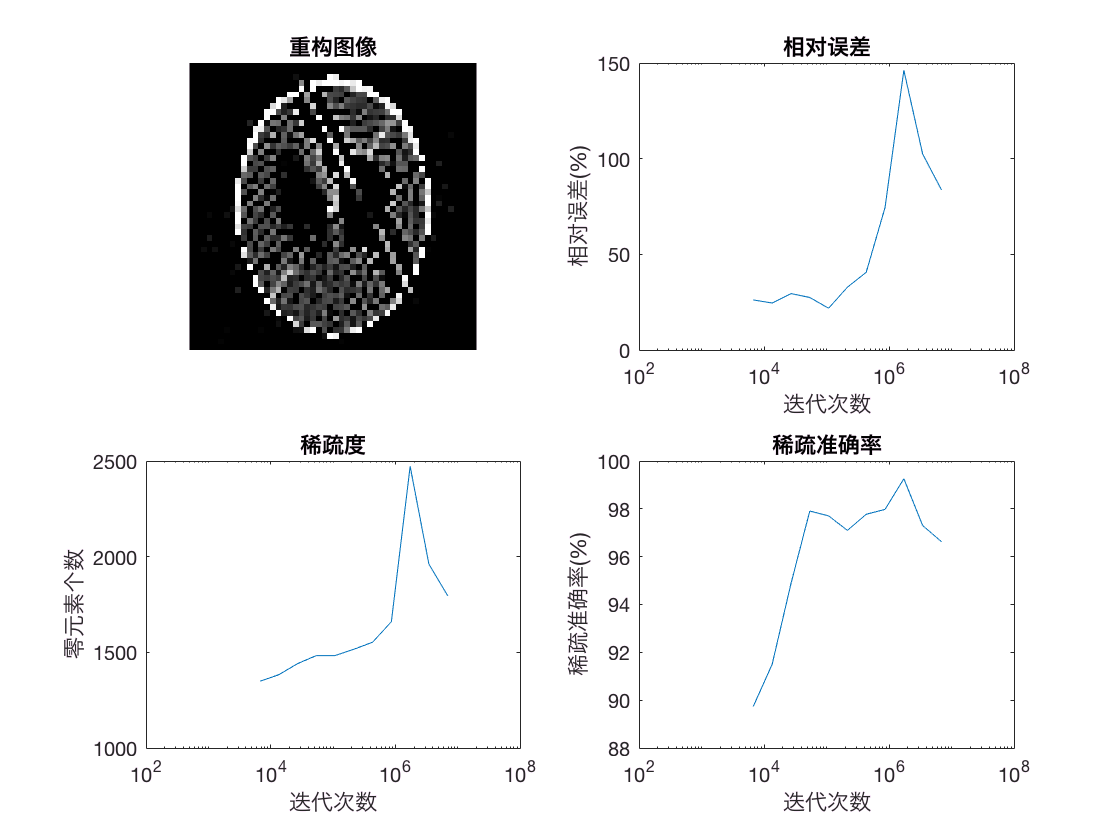

plotter.plot(X_RSK1)

相对误差下降至 0.873275 %


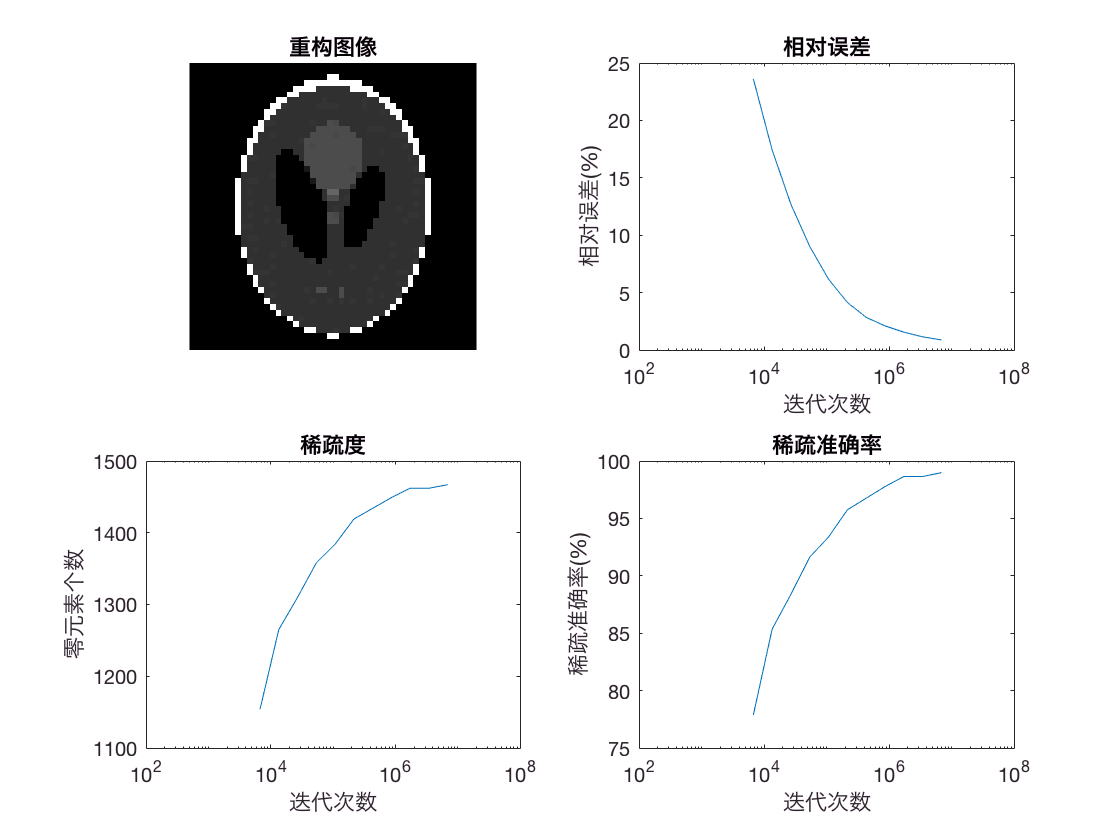

plotter.plot(X_RRSK)

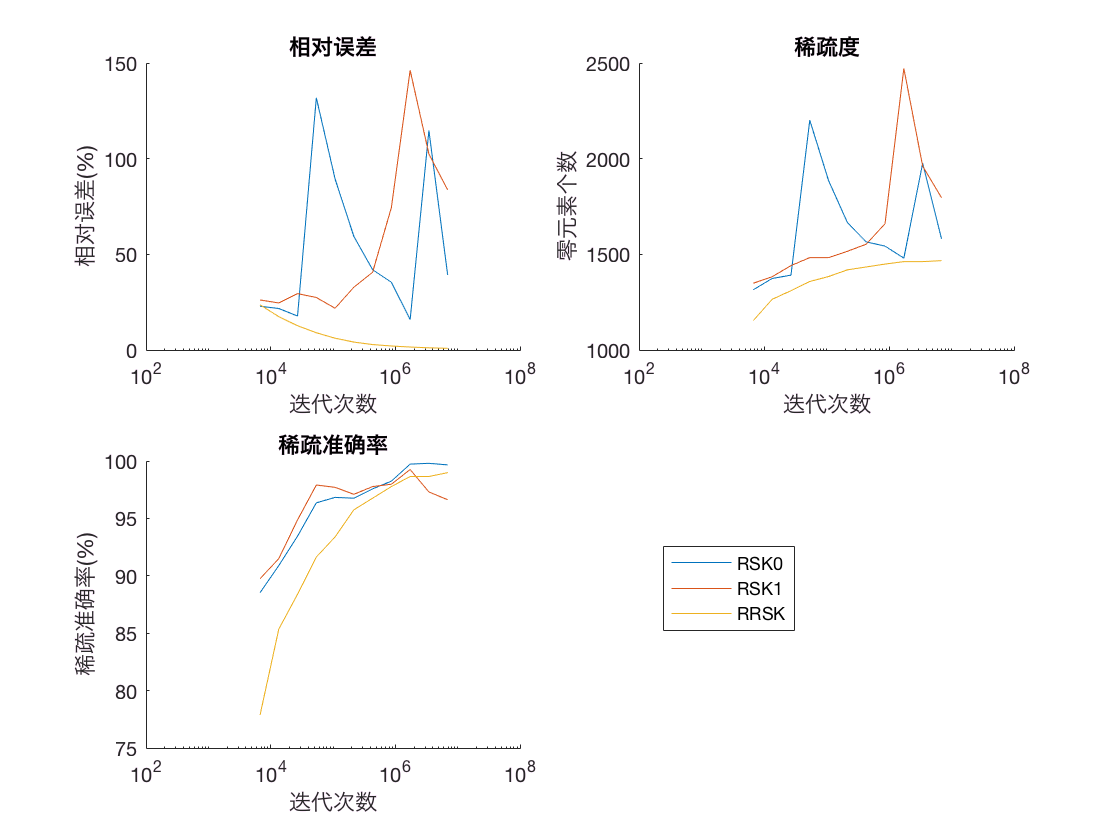

plotter.compare({'RSK0', 'RSK1', 'RRSK'}, X_RSK0, X_RSK1, X_RRSK)